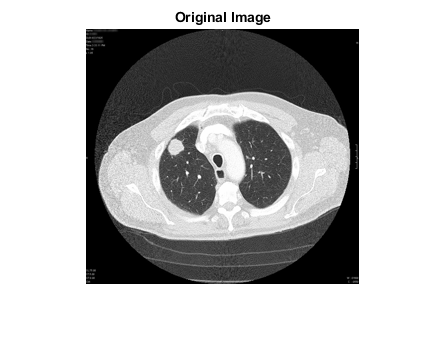

clc;
clear;
close all;

img = imread('LungCancer.jpg');
img = imresize(img, [255 NaN]);
imshow(img);title('Original Image');

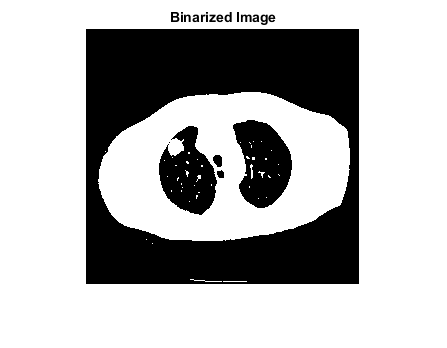

level = graythresh(img);
img_bin = rgb2gray(img);
img_bin = imbinarize(img_bin, level);
imshow(img_bin);title('Binarized Image');

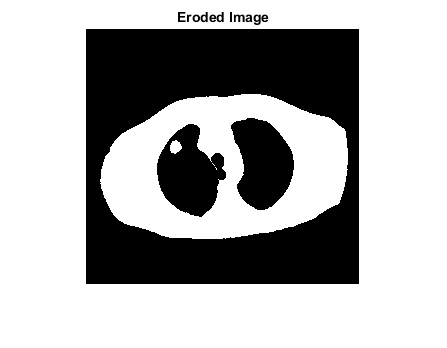

se = strel('diamond',2);
img_er = imerode(img_bin,se);
% img_er = bwmorph(img_bin,'erode',2.3);
imshow(img_er);title('Eroded Image');

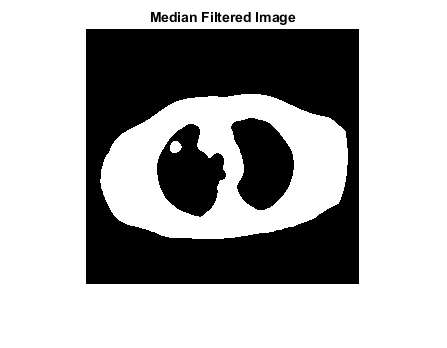

img_med = medfilt2(img_er, [5 5]);
imshow(img_med);title('Median Filtered Image');

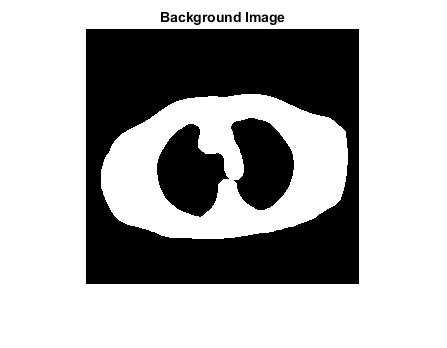

background = imopen(img_med,strel('disk',9));
imshow(background);title('Background Image')

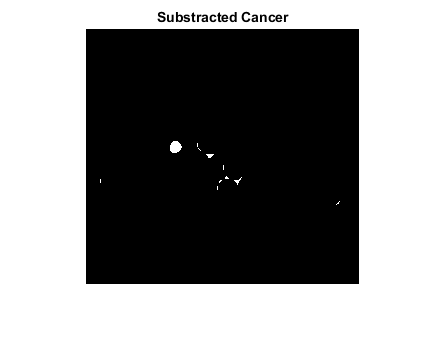

im_sub = imsubtract(img_med,background);
imshow(im_sub);title('Substracted Cancer');

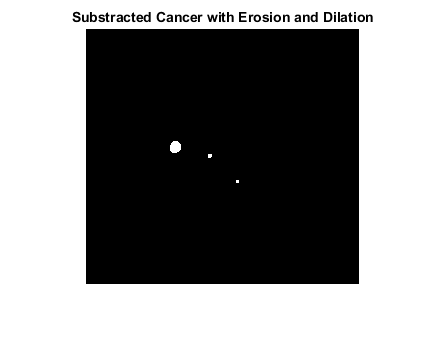

im_sub_er = bwmorph(im_sub,'erode',1);
im_sub_dil = bwmorph(im_sub_er,'dilate', 1);
imshow(im_sub_dil);title('Substracted Cancer with Erosion and Dilation');

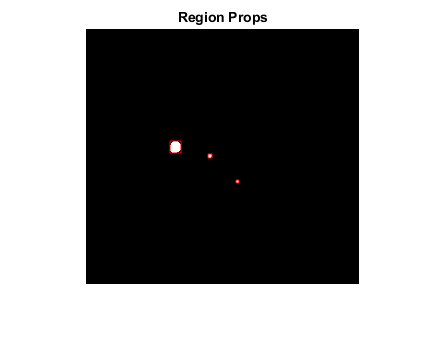

pixelH = 109

pixelH =    109    15


pixelH =    109    15     9


BWr = regionprops(im_sub_dil, 'BoundingBox', 'Area', 'Image');
figure, imshow(im_sub_dil), title('Region Props');
hold on;
pixelH = [];
pixelW = [];
for i=1:size(BWr,1)
    rectangle('Position', BWr(i).BoundingBox,'edgecolor','red');
%    pixelT = pixelT + BWr(i).Area;
    pixelH(1,i) = BWr(i).Area
end

cc = bwconncomp(im_sub_dil)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [255 273]
      NumObjects: 3
    PixelIdxList: {[109×1 double]  [15×1 double]  [9×1 double]}


num = cc.NumObjects;

arr = sort(pixelH, 'descend');
arrMaxP = arr(1,num);
[c_max, idx_max] = max(arrMaxP);
T = 100

T = 100

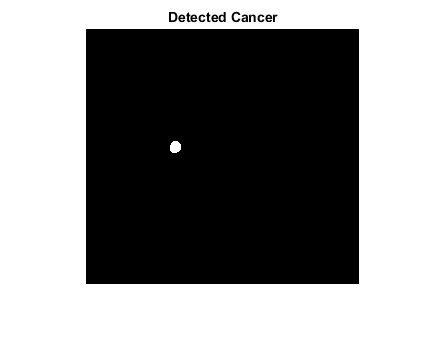




removeMask = [BWr.Area]<T;
BWremove2 = im_sub_dil;
BWremove2(cat(1, cc.PixelIdxList{removeMask})) = false;
BWremove2 = bwmorph(BWremove2, 'open', Inf);
imshow(BWremove2);


cc_rem = bwconncomp(BWremove2);
num_canc = cc_rem.NumObjects;

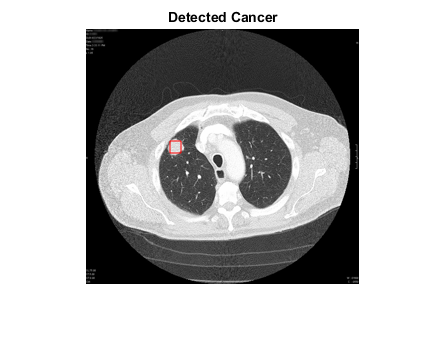

ans =      1     1



cancer = regionprops(BWremove2,'BoundingBox','Area');
 

 
imshow(img);title('Detected Cancer')
 
hold on ;

for cancers=1:size(cancer,1)
    size(cancer)
    rectangle('Position', cancer(cancers).BoundingBox,'edgecolor','red');
end

fprintf('***** ANALYSIS RESULT ******')

***** ANALYSIS RESULT ******

if (num_canc > 0)
    fprintf('This lung have cancer (abnormal)');
else
    fprintf('This lung is normal')
end

This lung have cancer (abnormal)